% Week 9 example code for training a simple CNN classifier on the
% CUB_200_2011_Subset20classes dataset.
%
% Author: Roland Goecke
% Date created: 26/04/2022
% Date last changed: 03/04/2023

close all;
clear variables;
clc;

## Read the training, validation and test partitions from the relevant

folder = "C:\Users\fazal_ix0ll8n\MATLAB\Projects\CV tutorials\week9\CUB_200_2011_Subset20classes\";
trainingImageNames = readtable(fullfile(folder, "train.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

targetSize = [224, 224];
trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);
labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);
labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);

## Display a sample image from the datastore

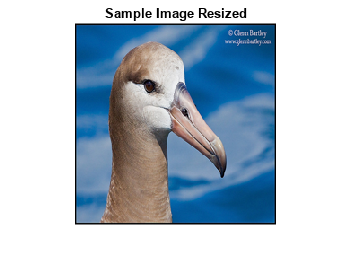

figure(1);
imshow(cdsTraining.read{1});
title('Sample Image Resized');

## Create a simple CNN

layers = [
    imageInputLayer([224 224 3])    % This needs to match the image size
    
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(20)
    softmaxLayer
    classificationLayer];

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index                     Name                      ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _______________________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3050 Ti Laptop GPU"          "8.6"               true              true      



## Set the training options

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.001, ...
    'MiniBatchSize', 20, ...
    'MaxEpochs', 5, ...
    'Verbose', true, ...
    'Shuffle', 'every-epoch', ...
    'VerboseFrequency', 1, ...
    'ValidationData', cdsValidation, ...
    'Plots','training-progress');

## Train the simple CNN model

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |        0.00% |        5.41% |       3.5719 |       3.7337 |          0.0010 |
|       1 |           2 |       00:00:10 |       10.00% |              |       3.3706 |              |          0.0010 |
|       1 |           3 |       00:00:10 |        0.00% |              |       4.0916 |              |          0.0010 |
|       1 |           4 |       00:00:11 |        5.00% |              |       4.5975 |   

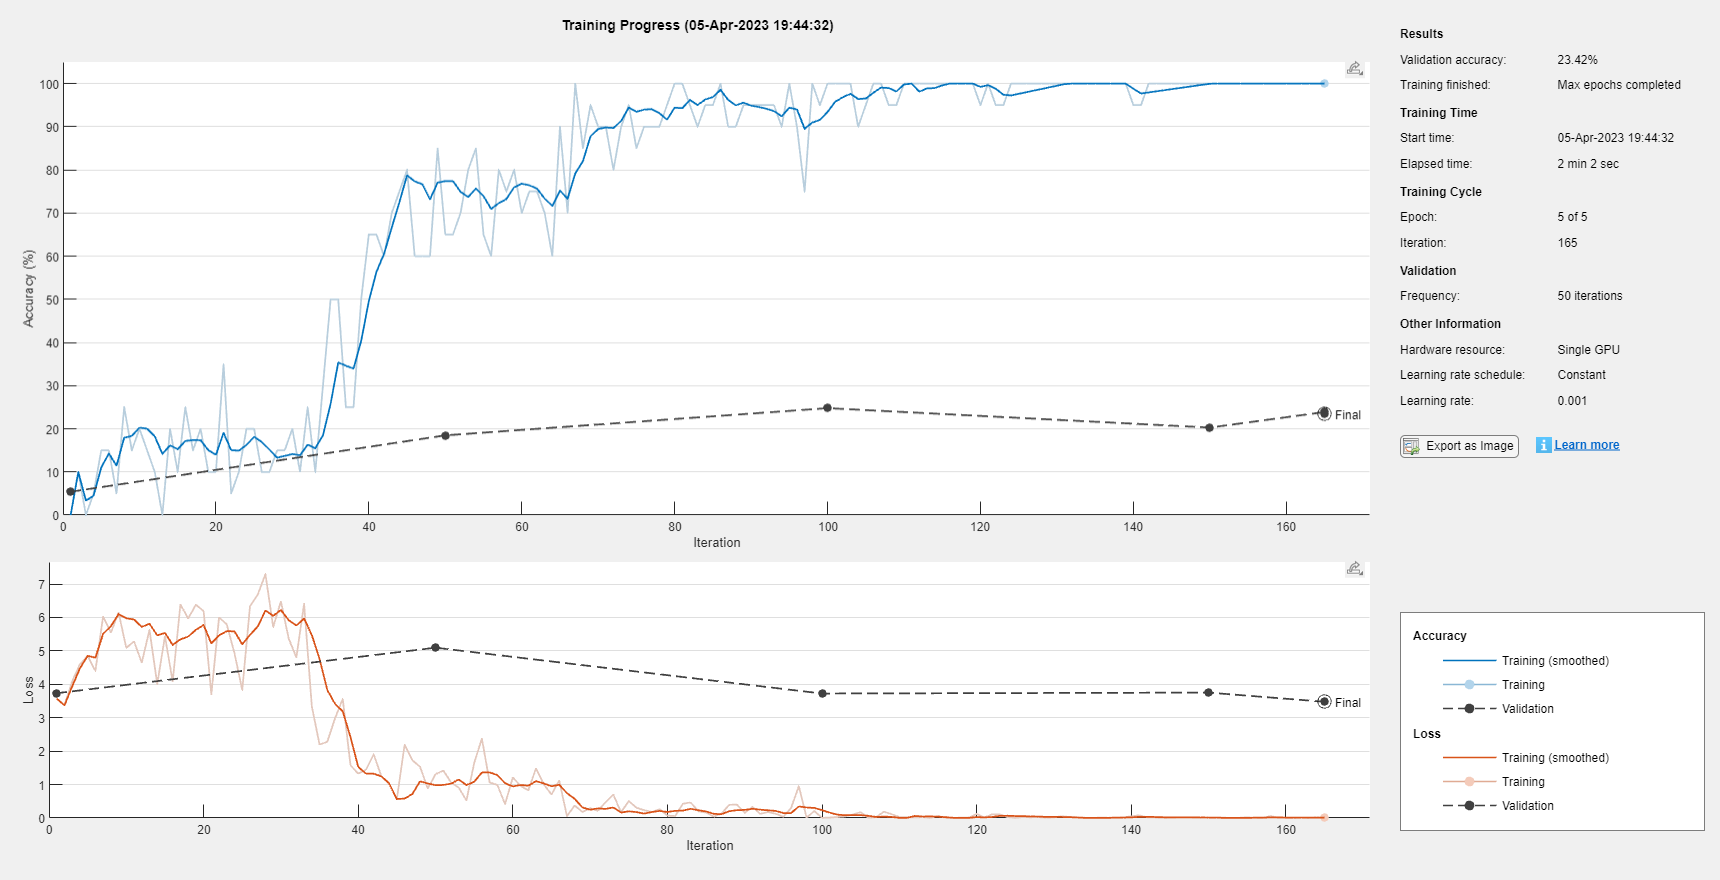

simpleCNN = trainNetwork(cdsTraining, layers, options);

## Test the accuracy on the test partition

YPred = classify(simpleCNN, testImageDS_Resized);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.2748

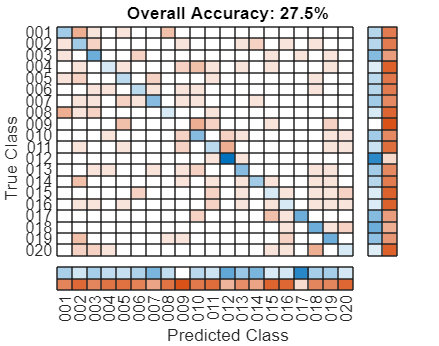


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%");